## Power System Protection: Distance protection 5

Consider the transmission loop shown in the single line diagram. 

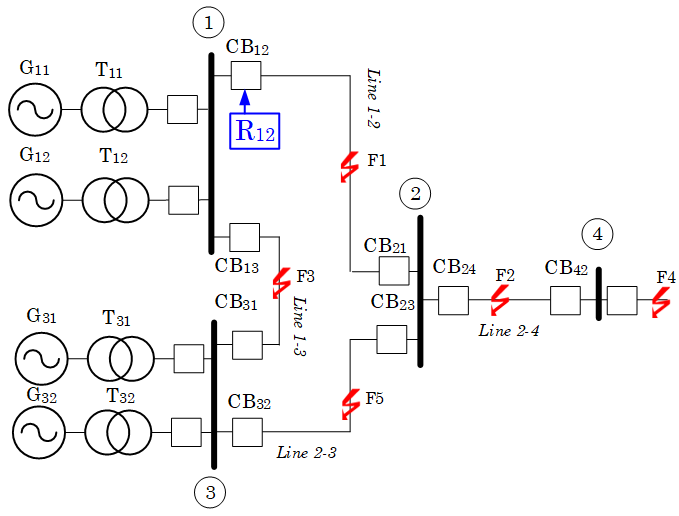                              

The rated voltage of the transmission system is 345 kV, and the positive-sequence impedance of the transmission lines are: 

*Z**12* = (4+*j32*)Ω

*Z**23* = (4+*j32*)Ω,

*Z**24* = (4+*j*32)Ω.

*Z**13 *= (4.3+*j*27)Ω.

A distance relay (mho-characteristic) is installed a CB1 (R12), and the instrument transformers have the following characteristics:

CT ratio: 1500 : 5

VT ratio: 3000 : 1

CConsidering a three-stepped distance protection scheme (Zones are depicted in the single-line diagram).

a) Define the appropriate protection zones of relay R12 in order to provide primary protection to the transmission line 1-2, and backup protection to lines 2-3 and 2-4 and remote backup to the neighbouring lines.

b) Determine the setting of** Zone 1** (80% reach) [Impedance and time].                

c) Determine the settings of **Zone 2** (120% reach, minimum setting) [Impedance and time].                                                                                                                     

d) Determine the setting of **Zone 3**. [Impedance and time]                                    

e) Maximum current for line 1-2 under emergency condition is 1,950 A, at power factor 0.93 lagging. Verify that the R12does not trip during the emergency loading conditions.                                                                                                           

Created by: Professor Francisco Gonzalez-Longatt, January 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

Github: [https://github.com/fglongatt](https://github.com/fglongatt)

ReserachGate: [https://www.researchgate.net/profile/Francisco_Gonzalez-Longatt](https://www.researchgate.net/profile/Francisco_Gonzalez-Longatt)

## Solution

clc
clear
% CT and VT transformers
CT = 1500/5

CT = 300

VT = 3000/1

VT = 3000

% lines imepdances
Z12 = 4 + 32*i

Z12 = 4.0000 + 32.0000i

Z23 = 4 + 32*i

Z23 = 4.0000 + 32.0000i

Z24 = 4 + 32*i

Z24 = 4.0000 + 32.0000i

Z13 = 4.3 + 27*i

Z13 = 4.3000 + 27.0000i

IL1 = 1950;
pf = 0.95;
VLN = 345e3/sqrt(3);

Using the CT and VT ratios , the secondary impedance viewed by the R12 impedance rcan be calculated

a = CT/VT

a = 0.1000

**Zone 1:**

Setting the R12 **Zone 1** relay for 80% reach, that is, 80% of line 1–2 (secondary) impedance:

Zone1 = a * 0.8 * (Z12);
fprintf(' ZR12zone1 = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(Zone1),imag(Zone1),abs(Zone1),angle(Zone1)*180/pi)

 ZR12zone1 = (0.32000 + j2.56000)Ω = (2.57992 ∠ 82.87498°)Ω

**Zone 2:**

Setting the R12 **Zone 2** relays for 120% reach:

Zone2 = a * ( 1.2* (Z12)  );
fprintf(' ZR12zone2 = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(Zone2),imag(Zone2),abs(Zone2),angle(Zone2)*180/pi)

 ZR12zone2 = (0.48000 + j3.84000)Ω = (3.86988 ∠ 82.87498°)Ω

**Zone 3:**

Setting the B12 **Zone 3** relays for 100% reach of line 1–2 (*Z*12) plus 120% reach of line 2–4 (*Z**24*).

Zone3 = a * ( 1.0* (Z12) +1.2 * Z24 );
fprintf(' ZR12zone3 = (%5.5f + j%5.5f)Ω = (%5.5f ∠%5.5f°)Ω',real(Zone3),imag(Zone3),abs(Zone3),angle(Zone3)*180/pi)

 ZR12zone3 = (0.88000 + j7.04000)Ω = (7.09479 ∠82.87498°)Ω

Now, consider the maximum current for line 1-2 under emergency condition is 1,400 A, at power factor 0.90 lagging. Let us investigate if the **R****12** does not trip during the emergency loading conditions.

 The secondary impedance (*Z’*) viewed by R12 during **emergency loading**, using

IL = IL1 * (exp( -i * (acos(pf) ) ) );
fprintf(' IL = (%5.5f + j%5.5f)A = (%5.5f ∠ %5.5f°)A',real(IL),imag(IL),abs(IL),angle(IL)*180/pi)

 IL = (1852.50000 + j-608.88730)A = (1950.00000 ∠ -18.19487°)A

As a consequence *Z’* results

Z = VLN / IL * a;
fprintf(' Z = (%5.5f + j %5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(Z),imag(Z),abs(Z),angle(Z)*180/pi)

 Z = (9.70393 + j 3.18953)Ω = (10.21466 ∠ 18.19487°)Ω

**Conclusion.** Since this impedance exceeds the Zone 3 setting, the impedance during emergency loading lies outside the trip regions of the three-zone, directional impedance relay. Also, lower line loadings during normal operation will result in even larger impedances farther away from the trip regions. R12 will trip during faults but not during normal and emergency loadings.